# QTRK for Tensor-Regression Video Deblur

clear;clc;close all;
addpath('../deblurring')
addpath('../tproduct toolbox 2.0 (transform)/')

### Initializing with Zero Tensor

openfig('figs/QTRK_deblurring_error_zeroinitialization.fig')

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [616 598 560 420]
       Units: 'pixels'

  Show all properties


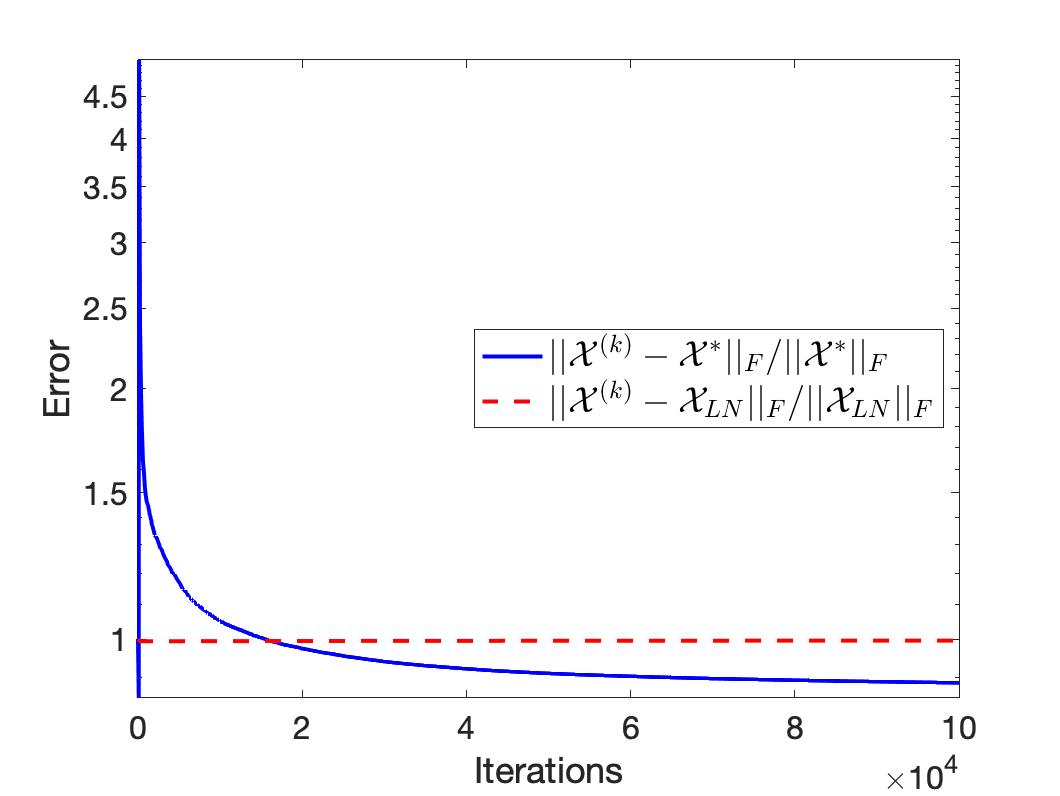

set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||_F/||\mathcal{X}^*||_F$', '$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}||_F/||\mathcal{X}_{LN}||_F$','FontSize',18,'Interpreter','latex','Location','east')
savefig('figs/QTRK_deblurring_error_zeroinitialization.fig')
saveas(gcf,'figs/QTRK_deblurring_error_zeroinitialization.png')

### Initializing with Noisy Image

openfig('figs/QTRK_deblurring_error_blurryinitialization.fig')

ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [1 1 1]
    Position: [616 598 560 420]
       Units: 'pixels'

  Show all properties


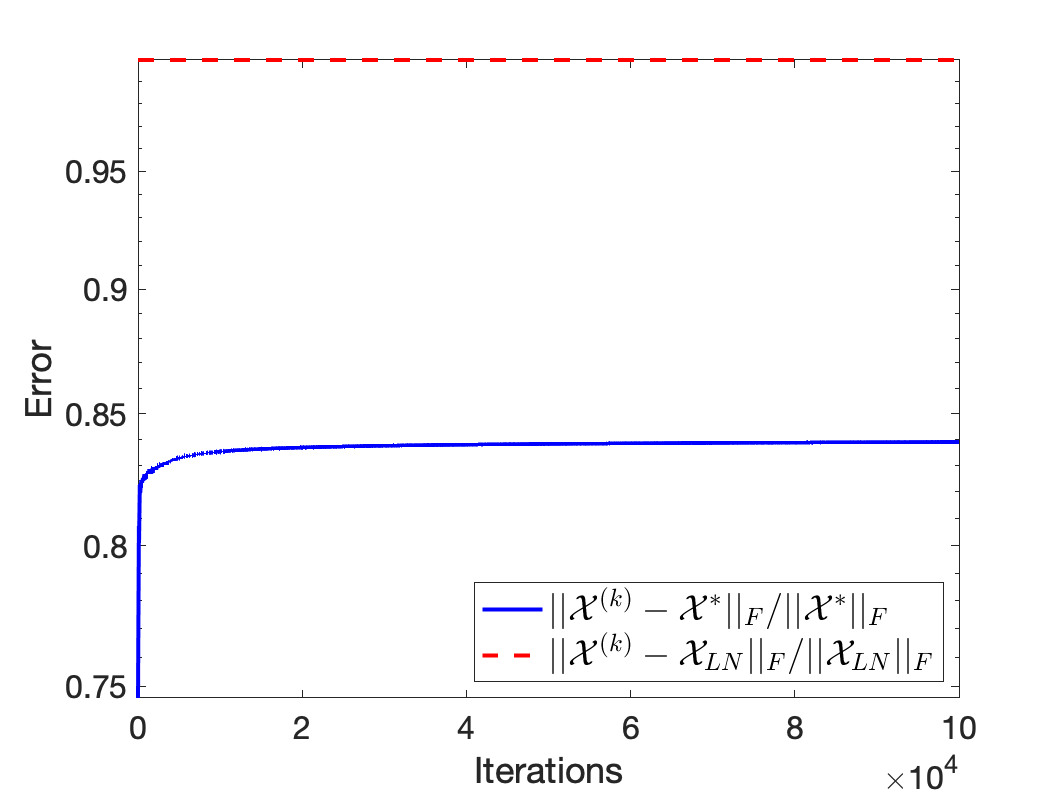

set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||_F/||\mathcal{X}^*||_F$', '$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}||_F/||\mathcal{X}_{LN}||_F$','FontSize',18,'Interpreter','latex','Location','southeast')
savefig('figs/QTRK_deblurring_error_blurryinitialization.fig')
saveas(gcf,'figs/QTRK_deblurring_error_blurryinitialization.png')

### Initializing randomly

openfig('figs/QTRK_deblurring_error_randinitialization.fig')

ans =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [1 1 1]
    Position: [616 598 560 420]
       Units: 'pixels'

  Show all properties


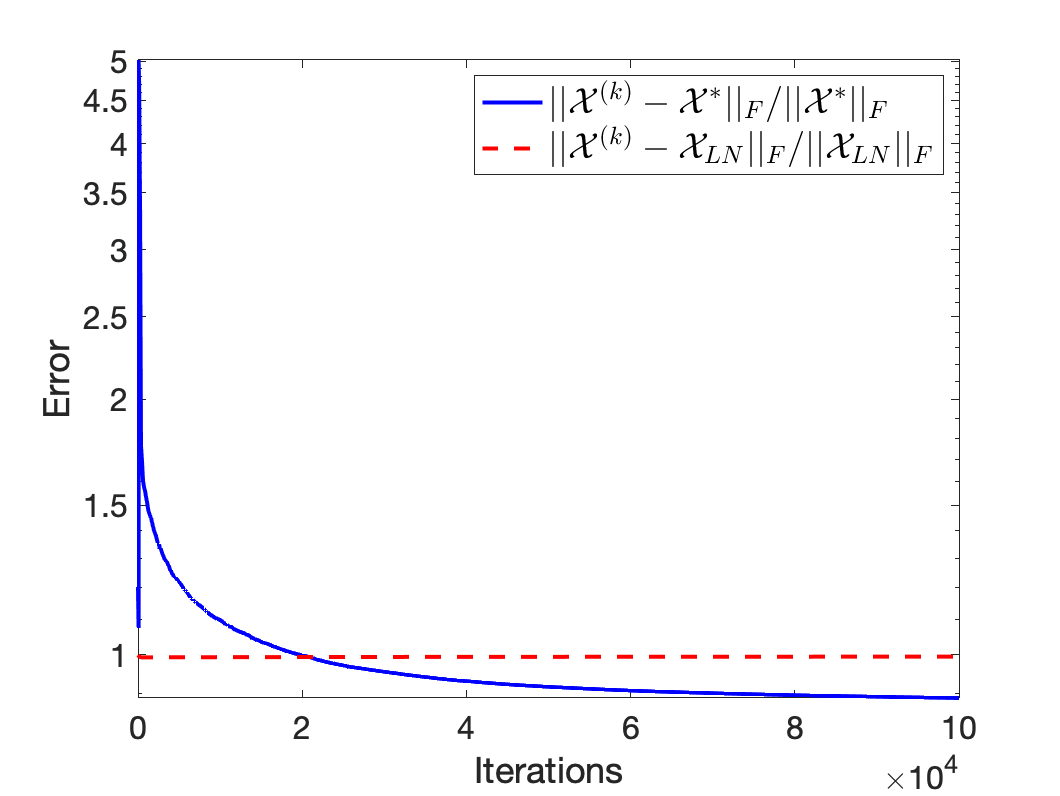

set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('Error','FontSize',18) 
legend('$||\mathcal{X}^{(k)} - \mathcal{X}^*||_F/||\mathcal{X}^*||_F$', '$||\mathcal{X}^{(k)} - \mathcal{X}_{LN}||_F/||\mathcal{X}_{LN}||_F$','FontSize',18,'Interpreter','latex','Location','northeast')
savefig('figs/QTRK_deblurring_error_randinitialization.fig')
saveas(gcf,'figs/QTRK_deblurring_error_randinitialization.png')

openfig('figs/QTRK_deblurring_reserror.fig')

ans =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [1 1 1]
    Position: [616 598 560 420]
       Units: 'pixels'

  Show all properties


set(gca,'FontSize',16)
xlabel('Iterations','FontSize',18) 
ylabel('$||\mathcal{A} \mathcal{X}^{(k)} - \mathcal{B}||_F$','FontSize',18,'Interpreter','latex') 
legend('zero initialization', 'blurry initialization', 'random initialization','FontSize',18,'Interpreter','latex','Location','northeast')
savefig('figs/QTRK_deblurring_reserror.fig')
saveas(gcf,'figs/QTRK_deblurring_reserror.png')